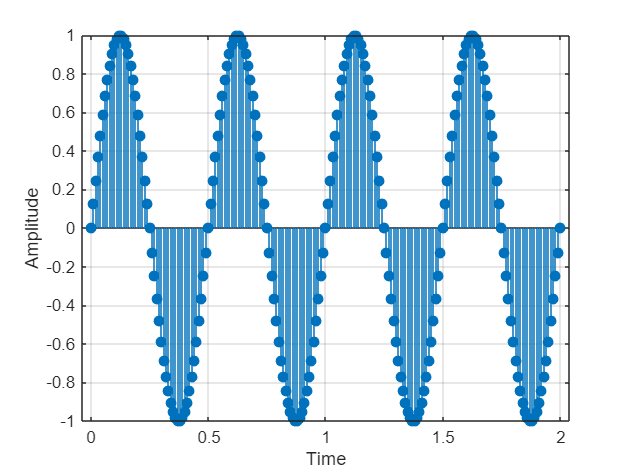

function x = gen(A, f, T, Fs)

n= 0:1/Fs:T;
x= A * sin(2*pi*f*n);
figure;
stem(n, x,'filled');
xlabel('Time');
ylabel('Amplitude');

grid on;
end

%1
x1 = gen(1, 2, 2, 100);

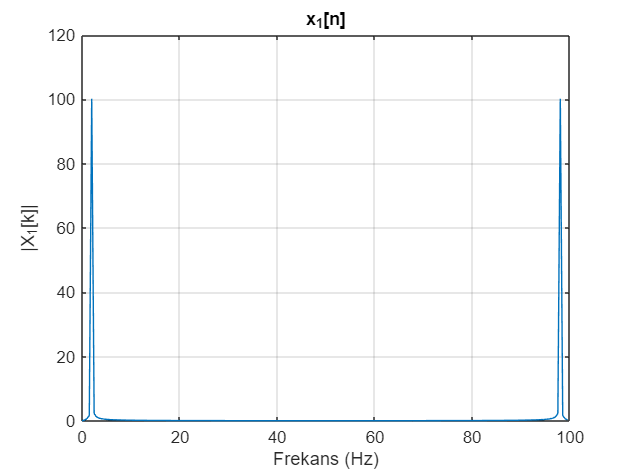


%2
N = length(x1); 
X1 = fft(x1, N); 

Fs=100;
f_axis = (0:N-1) * (Fs / N);


figure;
plot(f_axis, abs(X1));
xlabel('Frekans (Hz)');
ylabel('|X_1[k]|');
title('x_1[n]');
grid on;

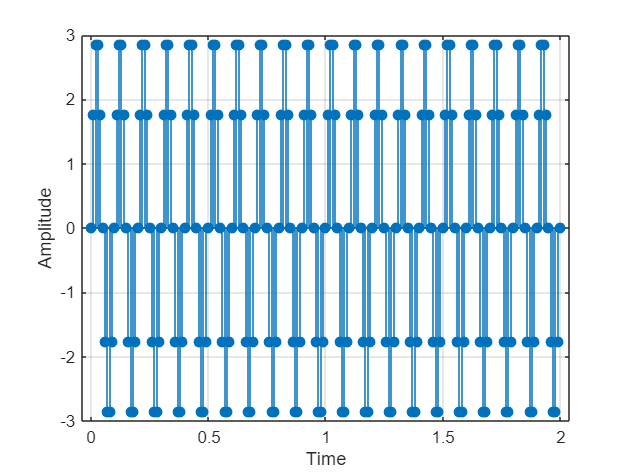


%3

x2 = gen(3, 10, 2, 100);

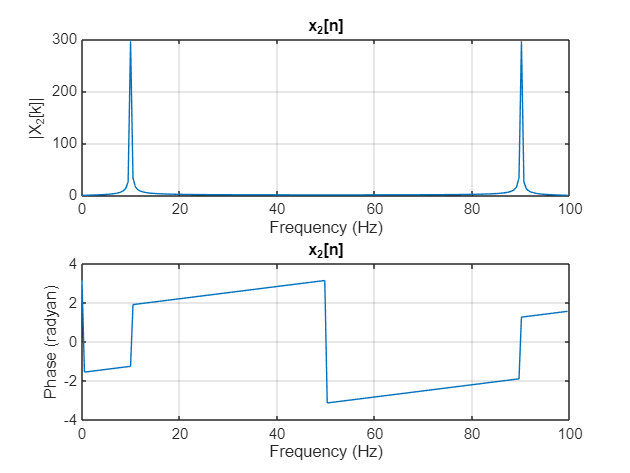



N = length(x2);
X2 = fft(x2, N);


Fs = 100;  
f_axis = (0:N-1) * (Fs / N);


figure;
subplot(2,1,1);
plot(f_axis, abs(X2));
xlabel('Frequency (Hz)');
ylabel('|X_2[k]|');
title('x_2[n]');
grid on;

subplot(2,1,2);
plot(f_axis, angle(X2));
xlabel('Frequency (Hz)');
ylabel('Phase (radyan)');
title('x_2[n]');
grid on;

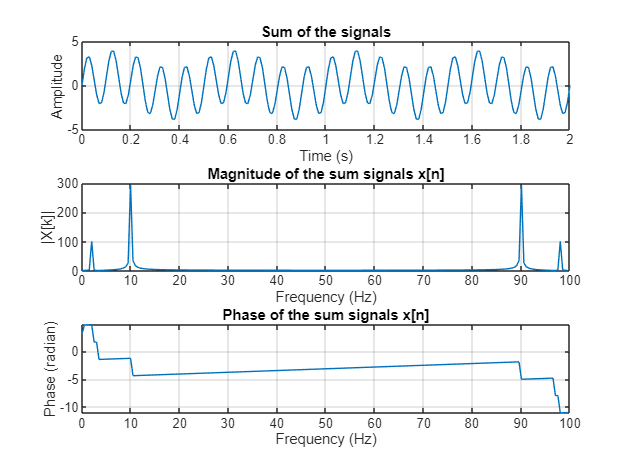




% 4

x = x1 + x2; 


N = length(x);
X = fft(x, N);


Fs = 100;
f_axis = (0:N-1) * (Fs / N);


figure;
subplot(3,1,1);
plot(0:1/Fs:2, x)
xlabel('Time (s)');
ylabel('Amplitude');
title('Sum of the signals');
grid on;


subplot(3,1,2);
plot(f_axis, abs(X));
xlabel('Frequency (Hz)');
ylabel('|X[k]|');
title('Magnitude of the sum signals x[n]');
grid on;


subplot(3,1,3);
plot(f_axis, unwrap(angle(X)));
xlabel('Frequency (Hz)');
ylabel('Phase (radian)');
title('Phase of the sum signals x[n]');
grid on;

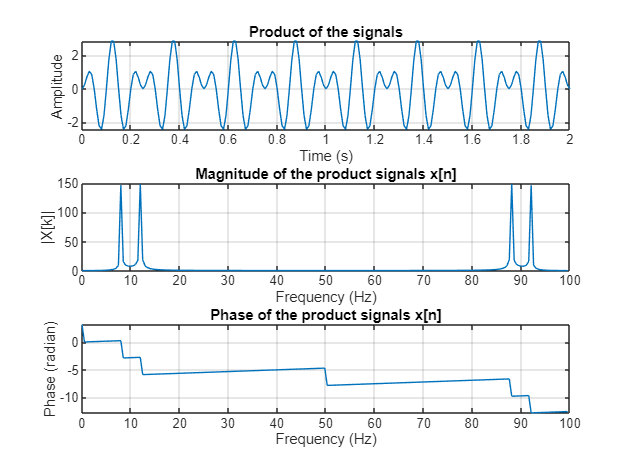


%5

x_mult = x1 .* x2; 


N = length(x_mult);
X_mult = fft(x_mult, N);


Fs = 100;
f_axis = (0:N-1) * (Fs / N);


figure;
subplot(3,1,1);
plot(0:1/Fs:2, x_mult);
xlabel('Time (s)');
ylabel('Amplitude');
title('Product of the signals');
grid on;


subplot(3,1,2);
plot(f_axis, abs(X_mult));
xlabel('Frequency (Hz)');
ylabel('|X[k]|');
title('Magnitude of the product signals x[n]');
grid on;


subplot(3,1,3);
plot(f_axis, unwrap(angle(X_mult)));
xlabel('Frequency (Hz)');
ylabel('Phase (radian)');
title('Phase of the product signals x[n]');
grid on;

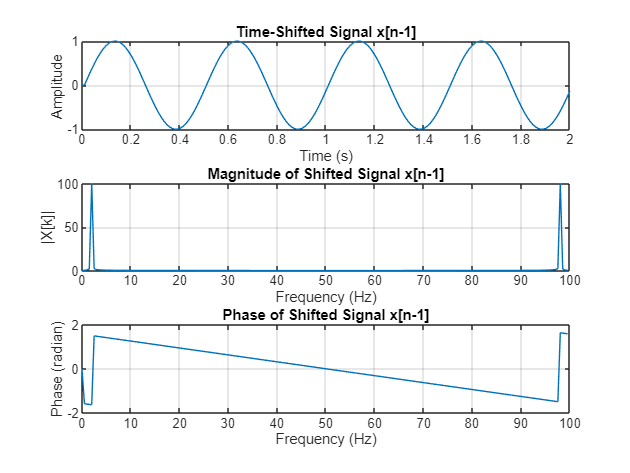





%6


x_shifted = [x1(end), x1(1:end-1)]; 


N = length(x_shifted);
X_shifted = fft(x_shifted, N);


Fs = 100;
f_axis = (0:N-1) * (Fs / N);


figure;
subplot(3,1,1);
plot(0:1/Fs:2, x_shifted);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Shifted Signal x[n-1]');
grid on;


subplot(3,1,2);
plot(f_axis, abs(X_shifted));
xlabel('Frequency (Hz)');
ylabel('|X[k]|');
title('Magnitude of Shifted Signal x[n-1]');
grid on;


subplot(3,1,3);
plot(f_axis, unwrap(angle(X_shifted)));
xlabel('Frequency (Hz)');
ylabel('Phase (radian)');
title('Phase of Shifted Signal x[n-1]');
grid on;

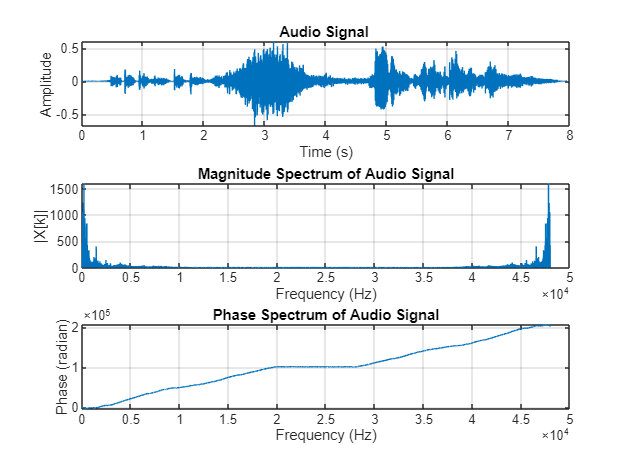


% 7



[audio, Fs_audio] = audioread('C:\Users\mehme\OneDrive\Desktop\DSP24-25\lab\1input.wav'); 

audio_segment = audio;


N_audio = length(audio_segment);
X_audio = fft(audio_segment, N_audio);


f_audio = (0:N_audio-1) * (Fs_audio / N_audio);


figure;
subplot(3,1,1);
plot((0:N_audio-1)/Fs_audio, audio_segment);
xlabel('Time (s)');
ylabel('Amplitude');
title('Audio Signal ');
grid on;


subplot(3,1,2);
plot(f_audio, abs(X_audio));
xlabel('Frequency (Hz)');
ylabel('|X[k]|');
title('Magnitude Spectrum of Audio Signal');
grid on;


subplot(3,1,3);
plot(f_audio, unwrap(angle(X_audio)));
xlabel('Frequency (Hz)');
ylabel('Phase (radian)');
title('Phase Spectrum of Audio Signal');
grid on;

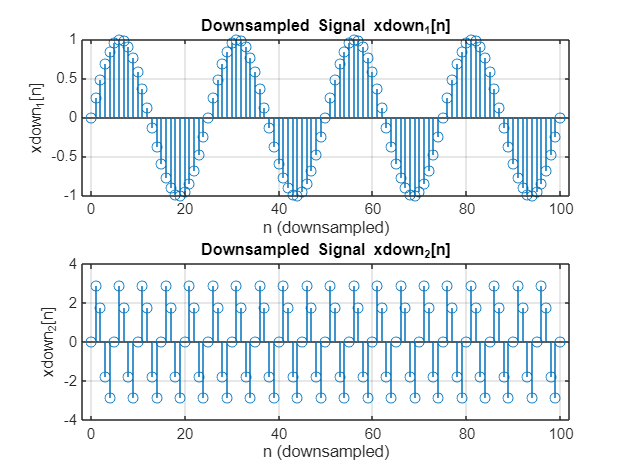



%%%%UP AND DOWN SAMPLING

% 2'ye down-sample işlemi 
xdown1 = x1(1:2:end);  
xdown2 = x2(1:2:end);  


figure;
subplot(2,1,1);
stem(0:length(xdown1)-1, xdown1);
xlabel('n (downsampled)');
ylabel('xdown_1[n]');
title('Downsampled Signal xdown_1[n]');
grid on;

subplot(2,1,2);
stem(0:length(xdown2)-1, xdown2);
xlabel('n (downsampled)');
ylabel('xdown_2[n]');
title('Downsampled Signal xdown_2[n]');
grid on;

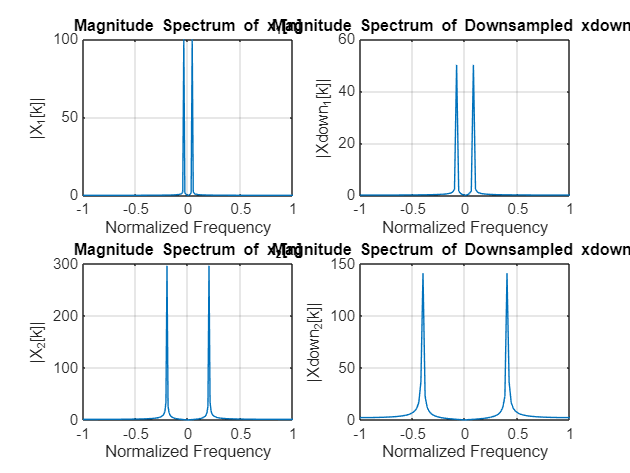

 
% FFT hesaplama
N1 = length(x1);
N2 = length(x2);
N_down1 = length(xdown1);
N_down2 = length(xdown2);

X1 = fft(x1, N1);
X2 = fft(x2, N2);
Xdown1 = fft(xdown1, N_down1);
Xdown2 = fft(xdown2, N_down2);

% Frekans eksenleri
f1 = linspace(-0.5, 0.5, N1) * 2;
f2 = linspace(-0.5, 0.5, N_down1) * 2;

% Spektrumları çiz
figure;
subplot(2,2,1);
plot(f1, abs(fftshift(X1)));
xlabel('Normalized Frequency');
ylabel('|X_1[k]|');
title('Magnitude Spectrum of x_1[n]');
grid on;

subplot(2,2,2);
plot(f2, abs(fftshift(Xdown1)));
xlabel('Normalized Frequency');
ylabel('|Xdown_1[k]|');
title('Magnitude Spectrum of Downsampled xdown_1[n]');
grid on;

subplot(2,2,3);
plot(f1, abs(fftshift(X2)));
xlabel('Normalized Frequency');
ylabel('|X_2[k]|');
title('Magnitude Spectrum of x_2[n]');
grid on;

subplot(2,2,4);
plot(f2, abs(fftshift(Xdown2)));
xlabel('Normalized Frequency');
ylabel('|Xdown_2[k]|');
title('Magnitude Spectrum of Downsampled xdown_2[n]');
grid on;

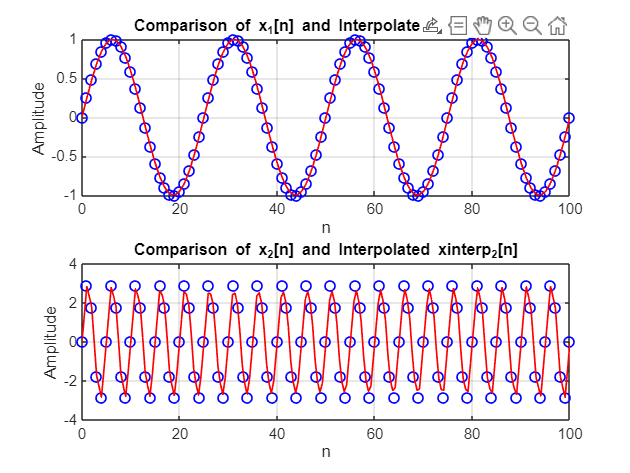


%

n_down = 0:length(xdown1)-1;  
n_interp = linspace(0, length(n_down)-1, length(n_down)*2); 


xinterp1 = interp1(n_down, xdown1, n_interp, 'linear', 'extrap');
xinterp2 = interp1(n_down, xdown2, n_interp, 'linear', 'extrap');


figure;
subplot(2,1,1);
plot(n_down, xdown1, 'bo', 'LineWidth', 1); hold on; 
plot(n_interp, xinterp1, 'r', 'LineWidth', 1);
xlabel('n');
ylabel('Amplitude');
title('Comparison of x_1[n] and Interpolated xinterp_1[n]');

grid on;

subplot(2,1,2);
plot(n_down, xdown2, 'bo', 'LineWidth', 1); hold on; % Downsampled sinyal
plot(n_interp, xinterp2, 'r', 'LineWidth', 1); % Interpolated sinyal
xlabel('n');
ylabel('Amplitude');
title('Comparison of x_2[n] and Interpolated xinterp_2[n]');

grid on;